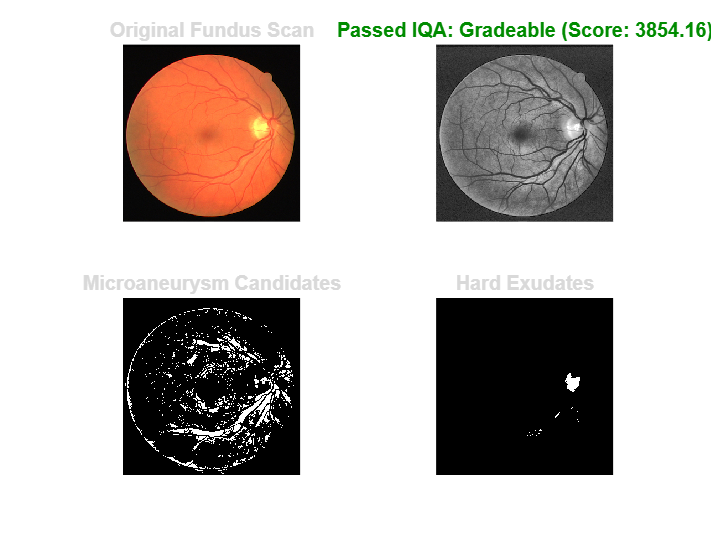

%% 1. Download and Read Sample Retinal Scan
img_url = 'https://raw.githubusercontent.com/JiajieMo/OctaveUNet/master/assets/fundus-image.jpg';
if ~exist('sample_fundus.jpg', 'file')
    websave('sample_fundus.jpg', img_url);
    disp('Sample fundus image downloaded successfully.');
end
img = imread('sample_fundus.jpg');

%% 2. Image Quality Assessment (Tenengrad Sharpness)
gray_img = rgb2gray(img);
Gx = imfilter(double(gray_img), fspecial('sobel')');
Gy = imfilter(double(gray_img), fspecial('sobel'));
tenengrad_score = mean(Gx(:).^2 + Gy(:).^2);

threshold_sharpness = 12.0; 
isGradeable = tenengrad_score >= threshold_sharpness;

%% 3. Adaptive Preprocessing (Green Channel CLAHE)
green_channel = img(:,:,2); 
clahe_img = adapthisteq(green_channel, 'ClipLimit', 0.02, 'Distribution', 'rayleigh');

%% 4. Lesion Candidate Isolation
% Optic disc suppression
se_disc = strel('disk', 30);
optic_disc_mask = imtophat(clahe_img, se_disc) > 210;

% Sub-pixel microaneurysms
se_ma = strel('disk', 6);
microaneurysms_candidates = imtophat(clahe_img, se_ma);
ma_binary = (microaneurysms_candidates > 35) & ~optic_disc_mask;

% Hard exudates
exudates_binary = (clahe_img > 195) & ~optic_disc_mask;

%% 5. Display Diagnostic Verification Panel
figure('Color', 'white');

subplot(2,2,1); 
imshow(img); 
title('Original Fundus Scan', 'FontWeight', 'bold');

subplot(2,2,2); 
imshow(clahe_img); 
if isGradeable
    title(sprintf('Passed IQA: Gradeable (Score: %.2f)', tenengrad_score), 'Color', [0 0.55 0], 'FontWeight', 'bold');
else
    title(sprintf('REJECT: Blurry (Score: %.2f)', tenengrad_score), 'Color', [0.8 0 0], 'FontWeight', 'bold');
end

subplot(2,2,3); 
imshow(ma_binary); 
title('Microaneurysm Candidates', 'FontWeight', 'bold');

subplot(2,2,4); 
imshow(exudates_binary); 
title('Hard Exudates', 'FontWeight', 'bold');
exportgraphics(gcf, 'diagnostic_verification_panel.png', 'Resolution', 300);